# Genetic algorithm for rating method

**INITIALISATION **Step 1: Establish 10 geometries for first generation


gen1Geometries = zeros(size(baseGeom,1), size(baseGeom,2), 10);
genNo = 1

genNo = 1


for k=1:10
    tempMat = zeros(size(baseGeom,1), size(baseGeom,2));
    for i=1:size(baseGeom,1)
        for j=1:size(baseGeom,2)
            if rand>0.3
                tempMat(i,j) = baseGeom(i,j);
            end
        end
    end
    outputMat = cleanSmallClusters(tempMat);
    outputGeometry(1,k,outputMat);
    gen1Geometries(:,:,k) = outputMat(:,:);
end


**VISUALS** Show intermediate result

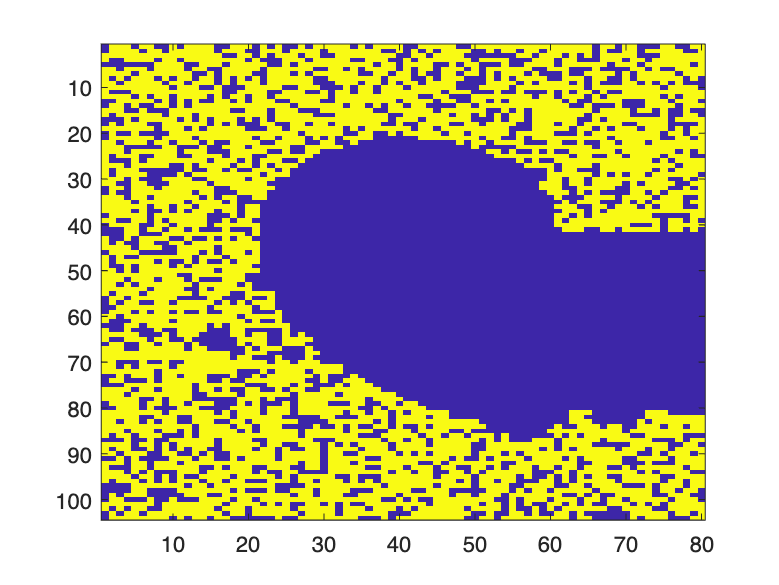

figure
imagesc(gen1Geometries(:,:,1));

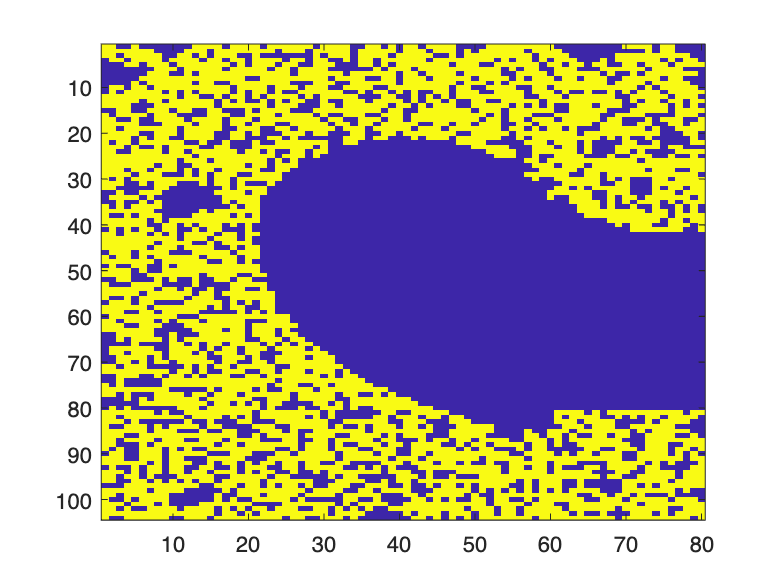

figure
imagesc(gen1Geometries(:,:,2));

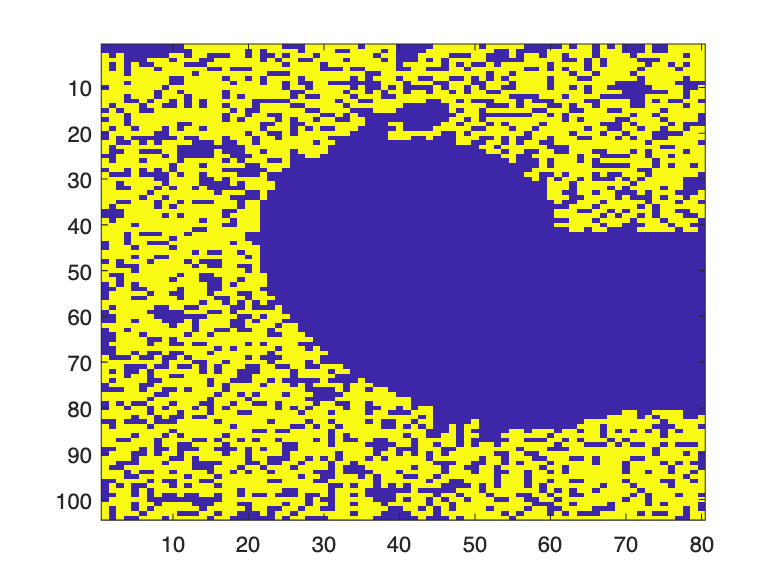

figure
imagesc(gen1Geometries(:,:,3));

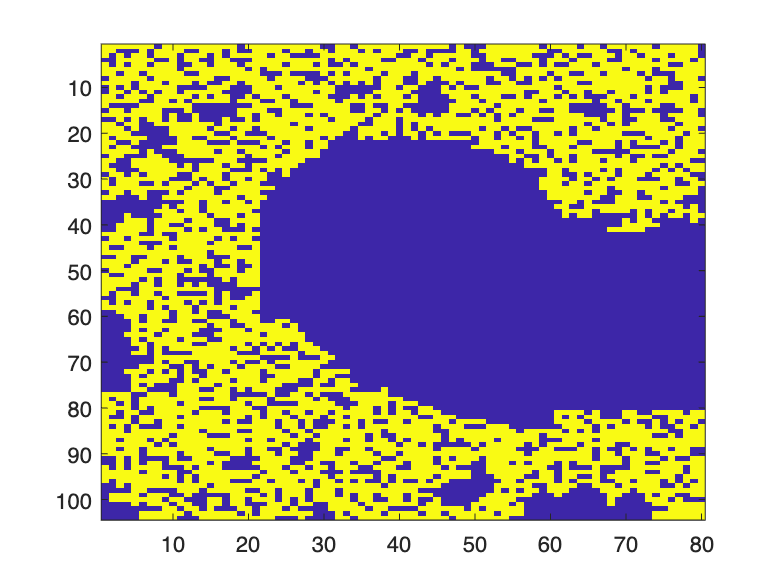

figure
imagesc(gen1Geometries(:,:,4));

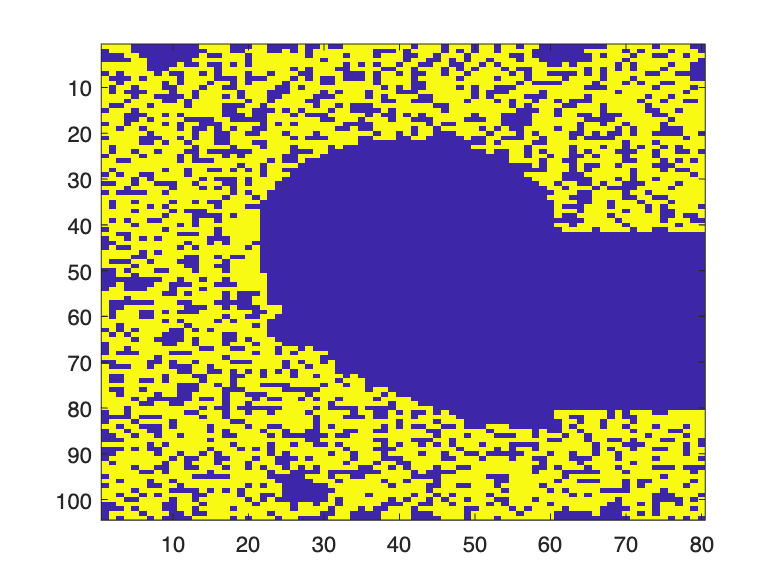

figure
imagesc(gen1Geometries(:,:,5));

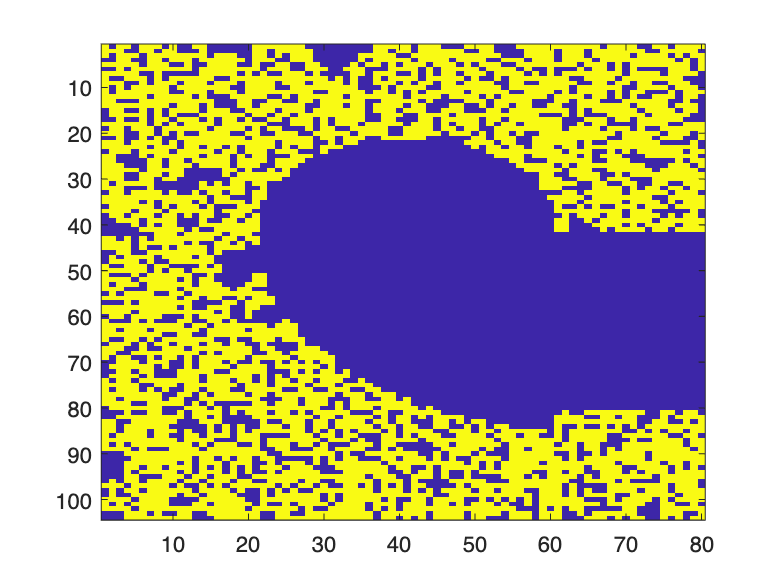

figure
imagesc(gen1Geometries(:,:,6));

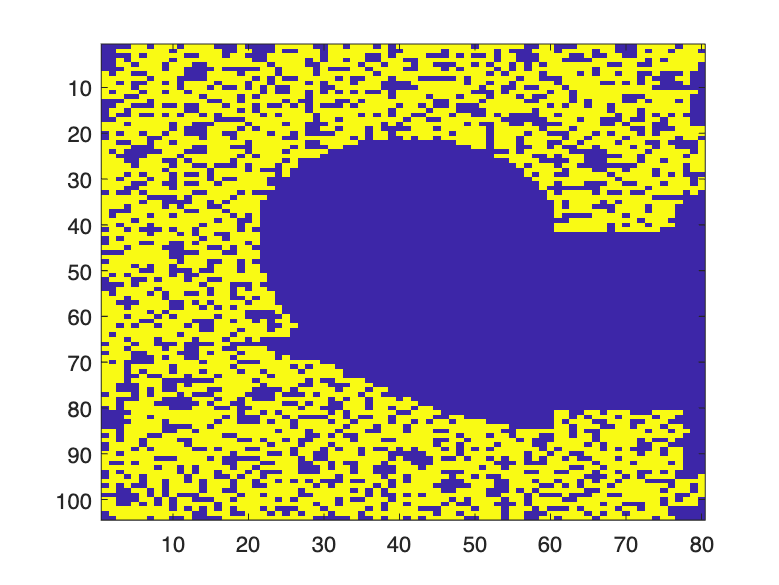

figure
imagesc(gen1Geometries(:,:,7));

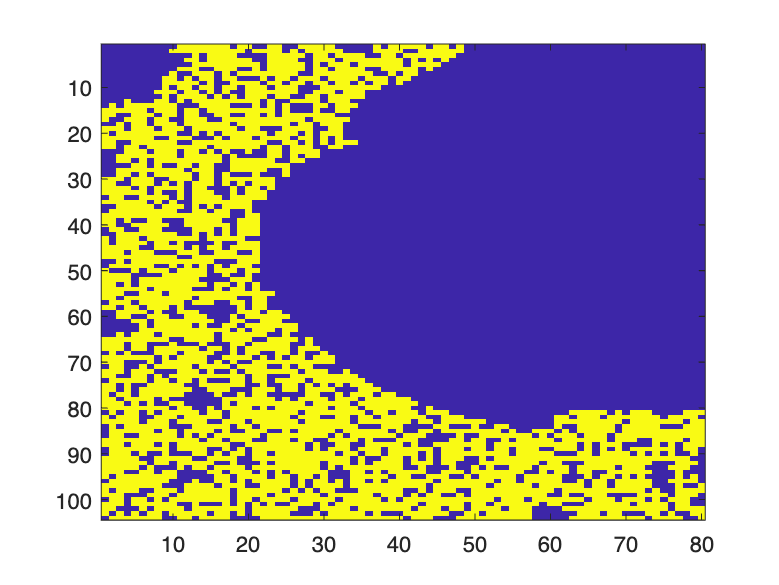

figure
imagesc(gen1Geometries(:,:,8));

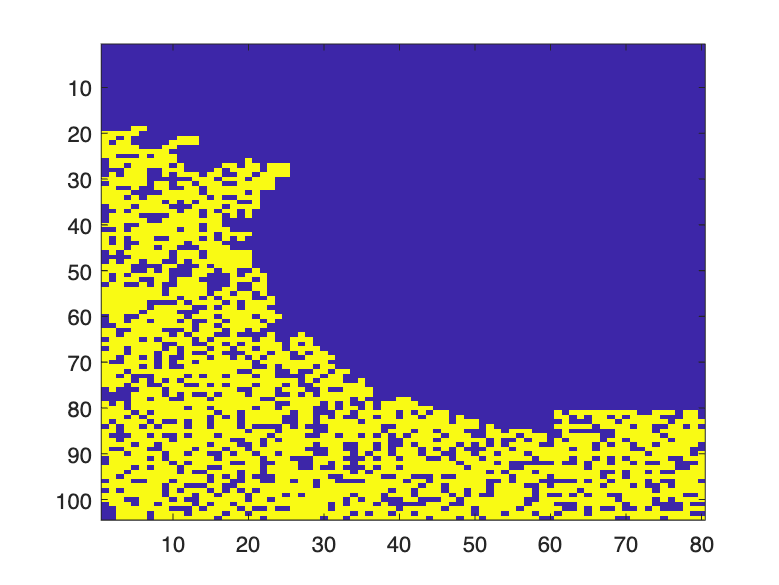

figure
imagesc(gen1Geometries(:,:,9));

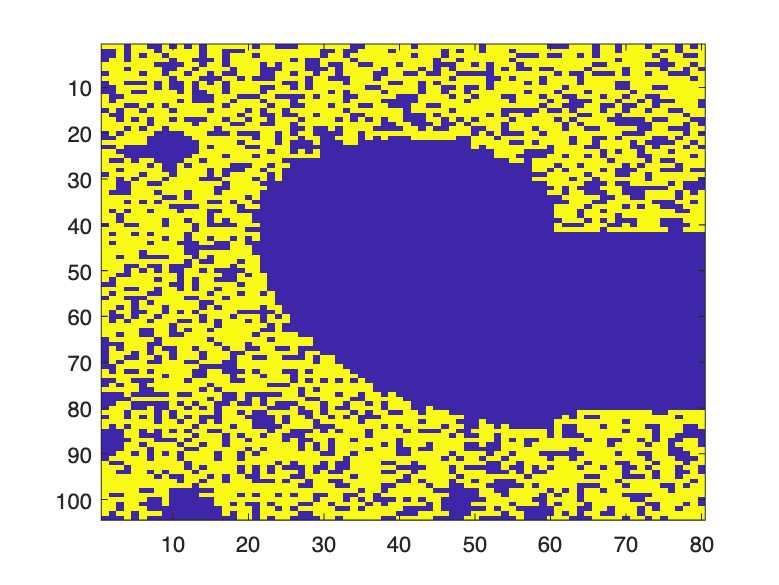

figure
imagesc(gen1Geometries(:,:,10));

**INITIALISATION **Step 2: create bank for printer, material, settings

% genIParam(J,1)
% printer 1: ender v3
% printer 2: ultimaker
Printer = [1 2];

% genIParam(J,2)
% Material brands are different for ender & ultimaker
% material 1: pla
% material 2: petg
% material 3: abs
Material = [1 2 3];

% genIParam(J,3)
% resolutions are different for ender & ultimaker
%           ender               ultimaker
% res 1:    Low quality         Fast
% res 2:    Standard quality    Normal
% res 3:    Dynamic quality     Fine
% res 4:    Super quality       Extra Fine
Resolution = [1 2 3 4];

% genIParam(J,4)
% infill density
%   1:  0%
%   2:  10%
%   3:  20%
%   4:  30%
%   5:  40%
%   6:  50%
%   7:  60%
%   8:  70%
%   9:  80%
%   10: 90%
%   11: 100%
InfillDensity = [1 2 3 4 5 6 7 8 9 10];

% genIParam(J,5)
% infill pattern
%   1:  Grid
%   2:  Lines
%   3:  Triangles
%   4:  Tri-Hexagon
%   5:  Cubic
%   6:  Cubic Subdivision
%   7:  Octet
%   8:  Quarter Qubic
%   9:  Concentric
%   10: Zig Zag
%   11: Cross
%   12: Cross 3D
%   13: Gyroid
%   14: Lightning
InfillPattern = [1 2 3 4 5 6 7 8 9 10 11 12 13 14];

% genIParam(J,6) 
% shell thickness Y = i*0.1 + 0.3
ShellThicknessY = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27];

% genIParam(J,7)
% shell thickness X = i*0.1 + 0.5
ShellThicknessX = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25];


**INITIALISATION **Step 3: pick random numbers for each of the parameters (1st gen)


gen1Parameters = zeros(10, 7);
parameterStock = [2 3 4 10 14 27 25];
for j=1:10
    for k=1:7
        gen1Parameters(j,k) = randi(parameterStock(k));
    end
end


**INITIALISATION **Step 4: Input results from tests

gen1Results = [0 0 0 0 0 0 0 0 0 0] %kg

gen1Results =      0     0     0     0     0     0     0     0     0     0



outputParameterSet(1,gen1Parameters);

outputResults(1,gen1Results);

outputVectorIOML(1,gen1Geometries, gen1Parameters);


**RECURRING **Step 5: Mating

gen2Geometries = zeros(size(baseGeom,1), size(baseGeom,2), 10);
gen2Parameters = zeros(10, 7);

matingSequence = randperm(10,10);
for k=1:5
    parent1G = gen1Geometries(:,:,matingSequence(k));
    parent2G = gen1Geometries(:,:,matingSequence(k+5));

    parent1P = gen1Parameters(matingSequence(k),:);
    parent2P = gen1Parameters(matingSequence(k+5),:);
    for i=1:110
        for j=1:60
            if rand>0.5
                gen2Geometries(i,j,k)=parent1G(i,j);
                gen2Geometries(i,j,k+5)=parent2G(i,j);
            else
                gen2Geometries(i,j,k+5)=parent1G(i,j);
                gen2Geometries(i,j,k)=parent2G(i,j);
            end
        end
    end

    for i=1:7
        if rand>0.5
            gen2Parameters(k,i)=parent1P(i);
            gen2Parameters(k+5,i)=parent2P(i);
        else
            gen2Parameters(k+5,i)=parent1P(i);
            gen2Parameters(k,i)=parent2P(i);
        end
    end

    mutationGrade(k) = 25*(gen1Results(matingSequence(k)) + gen1Results(matingSequence(k+5)));
    mutationGrade(k+5) = 25*(gen1Results(matingSequence(k)) + gen1Results(matingSequence(k+5)));
end


**RECURRING **Step 6: mutate occasional entries

for k=1:10
    for i=1:110
        for j=1:60
            if mutationGrade(k) < 1
                mutationGrade(k)=1;
            end
            if rand<(1/mutationGrade(k))
                if gen2Geometries(i,j,k)==0
                    gen2Geometries(i,j,k)=baseGeom(i,j);
                end
            end
            if rand<(1/mutationGrade(k))
                gen2Geometries(i,j,k)=0;
            end
        end
    end

    gen2Geometries(:,:,k) = cleanSmallClusters(gen2Geometries(:,:,k));

    for i=1:7
        if rand<(1/mutationGrade(k))
            gen2Parameters(k,i)=randi(parameterStock(i));
        end
    end
end

**VISUALS** Step 6.a: show intermediate results

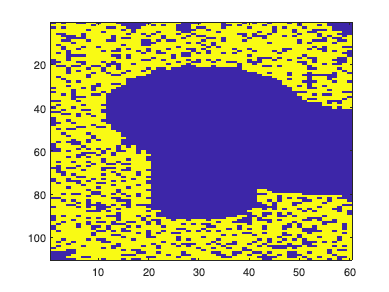

figure
imagesc(gen2Geometries(:,:,1));

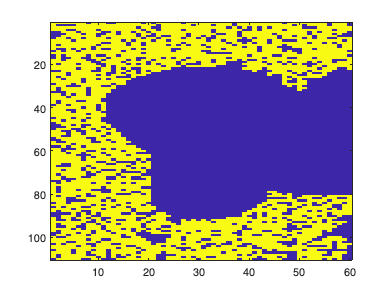

figure
imagesc(gen2Geometries(:,:,2));

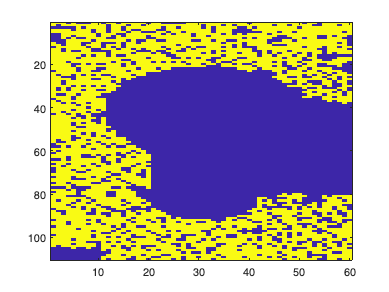

figure
imagesc(gen2Geometries(:,:,3));

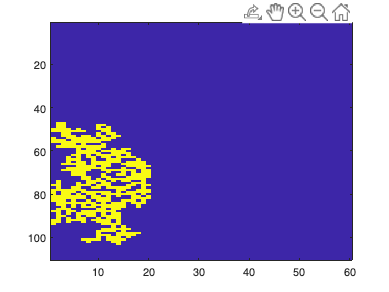

figure
imagesc(gen2Geometries(:,:,4));

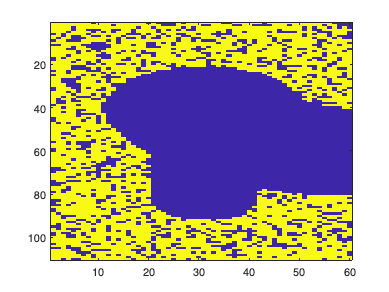

figure
imagesc(gen2Geometries(:,:,5));

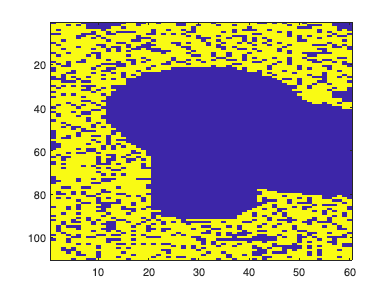

figure
imagesc(gen2Geometries(:,:,6));

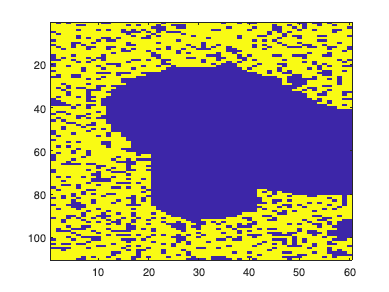

figure
imagesc(gen2Geometries(:,:,7));

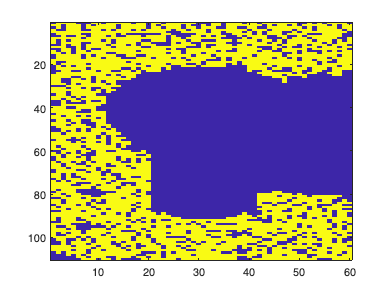

figure
imagesc(gen2Geometries(:,:,8));

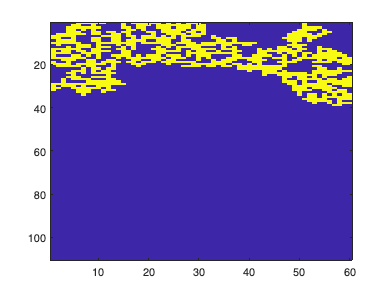

figure
imagesc(gen2Geometries(:,:,9));

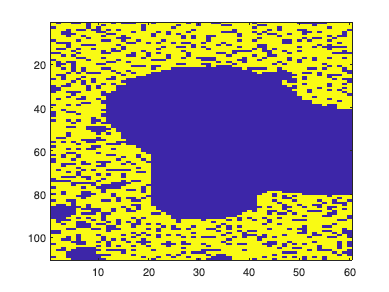

figure
imagesc(gen2Geometries(:,:,10));

**RECURRING **Step 7: perform tests for gen 2 and input results 

gen2Results = [5 5 5 5 5 10 10 10 10 10] %kg

gen2Results =      0     0     5     0     0     0     7     8     3    10


**RECURRING **Step 8: Choose best performing specimen from tests 1 & 2 

genTempGeometries = zeros(size(baseGeom,1), size(baseGeom,2), 10);
genTempParameters = zeros(10, 7);
genTempResults = zeros(1,10);

for i=1:10
    [maxVal, maxInd] = max([gen1Results gen2Results]);
    if maxInd < 11
        genTempResults(i) = gen1Results(maxInd);
        gen1Results(maxInd) = 0;
        genTempParameters(i,:) = gen1Parameters(maxInd,:);
        genTempGeometries(:,:,i) = gen1Geometries(:,:,maxInd);
    else
        genTempResults(i) = gen2Results(maxInd-10);
        gen2Results(maxInd-10) = 0;
        genTempParameters(i,:) = gen2Parameters(maxInd-10,:);
        genTempGeometries(:,:,i) = gen2Geometries(:,:,maxInd-10);
    end
end


**RECURRING **Step 9: Put the results into the prior generation (gen1)


gen1Geometries(:,:,:) = genTempGeometries(:,:,:);
gen1Parameters(:,:) = genTempParameters(:,:);
gen1Results(:,:) = genTempResults;


**RECURRING ****CHANGE GEN** Step 10: set the generation number and output results

genNo = 3 % CHANGE EVERY GENERATION

genNo = 3

for k=1:10
    outputGeometry(genNo,k,gen1Geometries(:,:,k));
end
outputParameterSet(genNo,gen1Parameters);
outputResults(genNo,gen1Results);

INTERNAL Recievs a matrix and defines the number of clusters and their coordinates

function [clusterCoordinates] = countClusters(matrix)
    [rows, cols] = size(matrix);
    labels = zeros(rows, cols);
    nextLabel = 1;
    clusterCoordinates = containers.Map('KeyType', 'double', 'ValueType', 'any');

    function exploreCluster(row, col)
        if row < 1 || row > rows || col < 1 || col > cols || labels(row, col) > 0 || matrix(row, col) == 0
            return;
        end
        labels(row, col) = nextLabel;
        if isKey(clusterCoordinates, nextLabel)
            clusterCoordinates(nextLabel) = [clusterCoordinates(nextLabel); [row, col]];
        else
            clusterCoordinates(nextLabel) = [row, col];
        end
        exploreCluster(row-1, col);
        exploreCluster(row+1, col);
        exploreCluster(row, col-1);
        exploreCluster(row, col+1);
    end

    for row = 1:rows
        for col = 1:cols
            if matrix(row, col) == 1 && labels(row, col) == 0
                exploreCluster(row, col);
                nextLabel = nextLabel + 1;
            end
        end
    end
end

Recievs a matrix and cleans the small clasters such that the biggest one remains

function [cleanMatrix] = cleanSmallClusters(dirtyMartrix)
    cleanMatrix = zeros(size(dirtyMartrix,1),size(dirtyMartrix,2));
    maxClusterNo = 0;
    maxClusterSize = 0;
    clusterCoordinates = countClusters(dirtyMartrix);

    for i=1:clusterCoordinates.Count
        tempClusterSize = size(clusterCoordinates(i),1) * size(clusterCoordinates(i),2);
        
        if(tempClusterSize > maxClusterSize)
            maxClusterSize = tempClusterSize;
            maxClusterNo = i;
        end
    end

    maxClusterCoordVec = clusterCoordinates(maxClusterNo);

    for i=1:size(maxClusterCoordVec,1)
        cleanMatrix(maxClusterCoordVec(i,1),maxClusterCoordVec(i,2)) = 1;
    end
end

Store a geometry in a text file via generation and part number

function [] = outputGeometry(genNo, ptNo, geomMatrix)
    genPath= ['GEN' num2str(genNo)];
    noPath= ['PART' num2str(ptNo)];

    writematrix(geomMatrix,[genPath '/' noPath '.txt'],'Delimiter',' ','WriteMode','overwrite')
end

Store parameter set in a text file via generation

function [] = outputParameterSet(genNo, parameterMatrix)
    genPath= ['GEN' num2str(genNo)];

    writematrix(parameterMatrix,[genPath '/param.txt'],'Delimiter',' ','WriteMode','overwrite')
end

Store result set in a text file via generation

function [] = outputResults(genNo, resultMatrix)
    genPath= ['GEN' num2str(genNo)];

    writematrix(resultMatrix',[genPath '/results.csv'],'Delimiter',' ','WriteMode','overwrite')
end

Output for ML model

function [] = outputVectorIOML(genNo, geomGenMatrix, parameterGenMatrix)
    genPath= ['GEN' num2str(genNo)];

    for k=1:10
        inputMat(k,:) = [reshape(geomGenMatrix(:,:,k).',1,[]) parameterGenMatrix(k,:)];
    end

    writematrix(inputMat,[genPath '/inputsML.csv'],'Delimiter',' ','WriteMode','overwrite')
end